per = 0

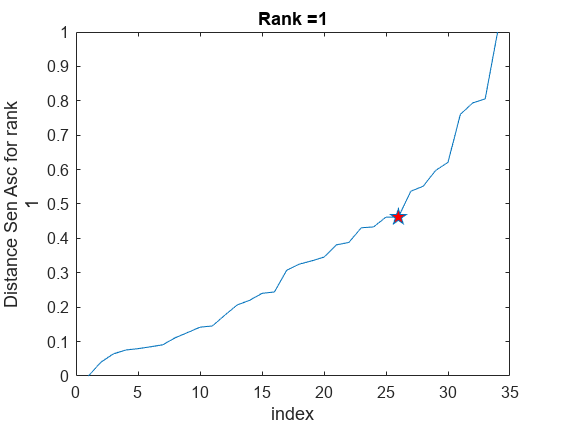

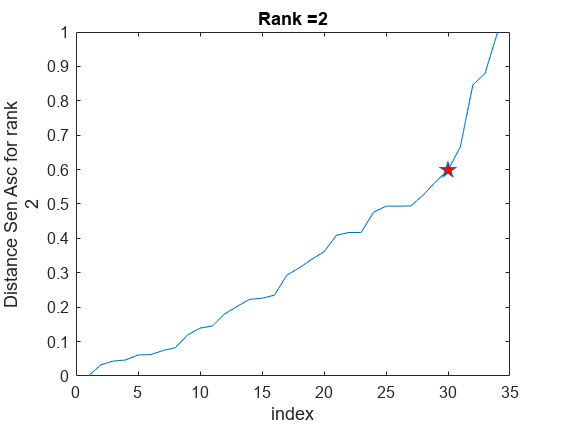

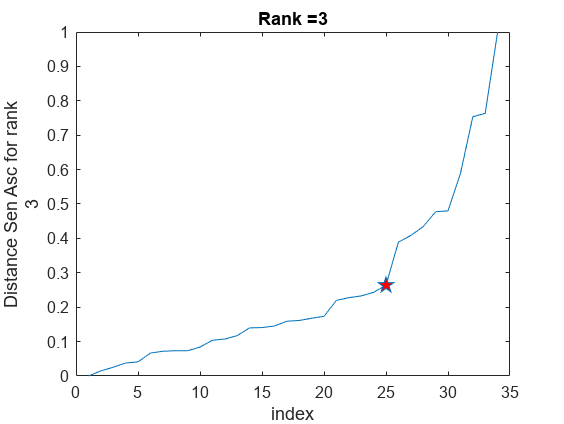

optrank_Sen = 2

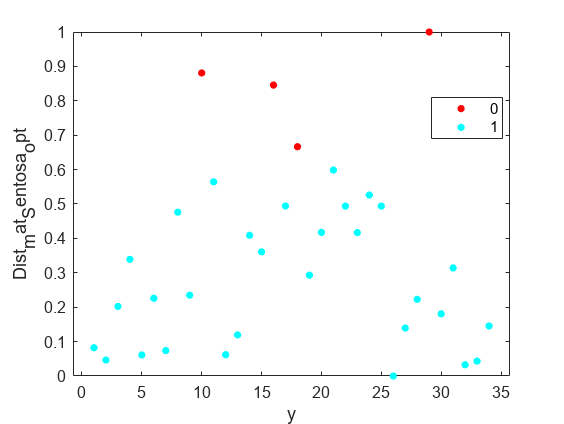

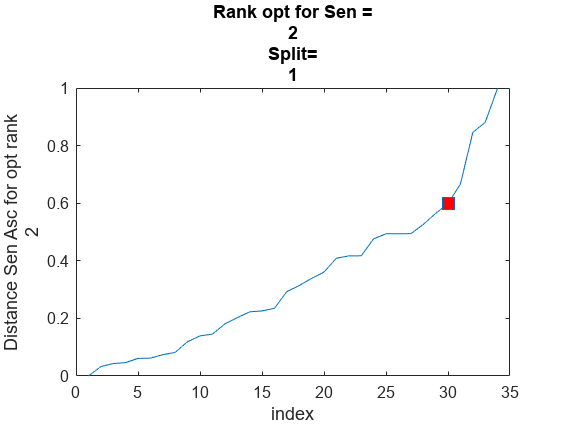

Unrecognized function or variable 'stratcat'.

for j = [1,2,3,4,5,6,7,8,9,10]

    splitfolder=strcat('split',num2str(j));

    per =0%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\Decision-Trees\
        cd (splitfolder)

        my_file = strcat('iris_train_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);
        %per_folder= strcat('per',num2str(per));

        Sentosa=File(File(:,5)==0,1:4);
        T_Sentosa=Sentosa.';
        T_Sentosa_org=Sentosa.';

        Versicolor=File(File(:,5)==1,1:4);
        T_Versicolor=Versicolor.';
        T_Versicolor_org=Versicolor.';

        Virginica=File(File(:,5)==2,1:4);
        T_Virginica=Virginica.';
        T_Virginica_org=Virginica.';

        folder=strcat('ACE_dist_optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder);
        cd (folder);

        ranks=[1,2,3];

        error_Sentosa = nan(size(ranks));
        numSentosa=length(T_Sentosa);
        Dist_mat_Sentosa_array_asc=nan(length(ranks),numSentosa);
        threshold_rank_Sen=nan(size(ranks));
        elbow_indx_rank_Sen=nan(size(ranks));


        for i = ranks
            %#fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Decision-Trees\

            T_Sentosa_temp=T_Sentosa;
            Dist_mat_Sentosa=[];


            BF_Sentosa=l1pca_BF(T_Sentosa,i,1,10,10,'');
            for k = 1 : numSentosa
                A=T_Sentosa(:,k);
                Dist_mat_Sentosa(k)=norm((A-(BF_Sentosa*BF_Sentosa.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_Sentosa,[],"all");
            max_val=max(Dist_mat_Sentosa,[],"all");
            Dist_mat_Sentosa= Dist_mat_Sentosa-min_val;%]/[max_val-min_val]
            Dist_mat_Sentosa=Dist_mat_Sentosa /(max_val-min_val);


            Dist_mat_Sentosa_array_asc(i,:)=Dist_mat_Sentosa;
            [Dist_mat_Sentosa_asc,Indx_Sen]=sort(Dist_mat_Sentosa,"ascend");


            [elbow_Sen_err_angle,elbow_indx_Sen]=knee_pt_angle(Dist_mat_Sentosa_asc);

            error_Sentosa(i)=elbow_Sen_err_angle;
            threshold_rank_Sen(i)=Dist_mat_Sentosa_asc(elbow_indx_Sen);
            elbow_indx_rank_Sen(i)=elbow_indx_Sen;


            figure
            plot(Dist_mat_Sentosa_asc,'-p',"MarkerIndices",(elbow_indx_Sen),'MarkerFaceColor','red','MarkerSize',10 )
            xlabel("index")
            ylabel(["Distance Sen Asc for rank", num2str(i)])
            title(['Rank =',num2str(i) ])
%             cd (splitfolder)
%             cd (folder)
            print(gcf,strcat('Sentosa',num2str(j),num2str(i),'.png'),'-dpng');

        end

        [~,optrank_Sen]= max(error_Sentosa)

        Dist_mat_Sentosa_opt=Dist_mat_Sentosa_array_asc(optrank_Sen,:);
        threshold_dist_Sen= threshold_rank_Sen(optrank_Sen);
        elbow_indx_Sen_opt=elbow_indx_rank_Sen(optrank_Sen);

        ind_O_Sen=find(Dist_mat_Sentosa_opt>threshold_dist_Sen);
        ind_I_Sen=find(Dist_mat_Sentosa_opt<=threshold_dist_Sen);


        cluster_Sen=zeros(size(Dist_mat_Sentosa_opt));
        cluster_Sen(ind_I_Sen)=1;
        figure
        y= 1:1:length(Sentosa);
        numGroups = length(unique(cluster_Sen));
        gscatter(y,Dist_mat_Sentosa_opt,cluster_Sen,hsv(numGroups))

        figure
        plot(sort(Dist_mat_Sentosa_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_Sen_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance Sen Asc for opt rank",num2str(optrank_Sen)])
        title(['Rank opt for Sen =',num2str(optrank_Sen),"Split=",num2str(j)])

        print(gcf,strcat('Rank_Opt_Sen',num2str(j),'.png'),'-dpng');

        
        
        ind_O_Sen;


        T_Sentosa_temp(:,ind_O_Sen)=[];
        length(T_Sentosa_temp);

        Final_Sentosa=T_Sentosa_temp';
        Final_Sentosa(:,5)=0;

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_Versicolor = nan(size(ranks));
        numVersicolor=length(T_Versicolor);
        Dist_mat_Versicolor_array_asc=nan(length(ranks),numVersicolor);
        threshold_rank_Ver=nan(size(ranks));
        elbow_indx_rank_Ver=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Decision-Trees\

            T_Versicolor_temp=T_Versicolor;
            Dist_mat_Versicolor=[];


            BF_Versicolor=l1pca_BF(T_Versicolor,i,1,10,10,'');
            for k = 1 : numVersicolor
                A=T_Versicolor(:,k);
                Dist_mat_Versicolor(k)=norm((A-(BF_Versicolor*BF_Versicolor.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_Versicolor,[],"all");
            max_val=max(Dist_mat_Versicolor,[],"all");
            Dist_mat_Versicolor= Dist_mat_Versicolor-min_val;%]/[max_val-min_val]
            Dist_mat_Versicolor=Dist_mat_Versicolor /(max_val-min_val);


            Dist_mat_Versicolor_array_asc(i,:)=Dist_mat_Versicolor;
            [Dist_mat_Versicolor_asc,Indx_Ver]=sort(Dist_mat_Versicolor,"ascend");


            [elbow_Ver_err,elbow_indx_Ver]=knee_pt_angle((Dist_mat_Versicolor_asc));

            error_Versicolor(i)=elbow_Ver_err;
            threshold_rank_Ver(i)=Dist_mat_Versicolor_asc(elbow_indx_Ver);
            elbow_indx_rank_Ver(i)=elbow_indx_Ver;

            figure
            plot(Dist_mat_Versicolor_asc,'-p',"MarkerIndices",(elbow_indx_Ver),'MarkerFaceColor','red','MarkerSize',10 )
            xlabel("index")
            ylabel(["Distance Ver Asc for rank", num2str(i)])
            title(['Rank =',num2str(i) ])
%             cd (splitfolder)
%             cd (folder)
            print(gcf,strcat('Versicolor',num2str(j),num2str(i),'.png'),'-dpng');
            


        end

        [~,optrank_Ver]= max(error_Versicolor)

        Dist_mat_Versicolor_opt=Dist_mat_Versicolor_array_asc(optrank_Ver,:);
        threshold_dist_Ver= threshold_rank_Ver(optrank_Ver);
        elbow_indx_Ver_opt=elbow_indx_rank_Ver(optrank_Ver);

        ind_O_Ver=find(Dist_mat_Versicolor_opt>threshold_dist_Ver);
        ind_I_Ver=find(Dist_mat_Versicolor_opt<=threshold_dist_Ver);


        cluster_Ver=zeros(size(Dist_mat_Versicolor_opt));
        cluster_Ver(ind_I_Ver)=1;
        figure
        y= 1:1:length(Versicolor);
        numGroups = length(unique(cluster_Ver));
        gscatter(y,Dist_mat_Versicolor_opt,cluster_Ver,hsv(numGroups))

        figure
        plot(sort(Dist_mat_Versicolor_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_Ver_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance Ver Asc for opt rank",num2str(optrank_Ver)])
        title(['Rank opt for Ver =',num2str(optrank_Ver),"Split=",num2str(j)])

        print(gcf,strcat('Rank_Opt_Versi',num2str(j),'.png'),'-dpng');

        ind_O_Ver;


        T_Versicolor_temp(:,ind_O_Ver)=[];
        length(T_Versicolor_temp);

        Final_Versicolor=T_Versicolor_temp';
        Final_Versicolor(:,5)=1;

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_Virginica = nan(size(ranks));
        numVirginica=length(T_Virginica);
        Dist_mat_Virginica_array_asc=nan(length(ranks),numVirginica);
        threshold_rank_Vir=nan(size(ranks));
        elbow_indx_rank_Vir=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Decision-Trees\

            T_Virginica_temp=T_Virginica;
            Dist_mat_Virginica=[];


            BF_Virginica=l1pca_BF(T_Virginica,i,1,10,10,'');
            for k = 1 : numVirginica
                A=T_Virginica(:,k);
                Dist_mat_Virginica(k)=norm((A-(BF_Virginica*BF_Virginica.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_Virginica,[],"all");
            max_val=max(Dist_mat_Virginica,[],"all");
            Dist_mat_Virginica= Dist_mat_Virginica-min_val;%]/[max_val-min_val]
            Dist_mat_Virginica=Dist_mat_Virginica /(max_val-min_val);


            Dist_mat_Virginica_array_asc(i,:)=Dist_mat_Virginica;
            [Dist_mat_Virginica_asc,Indx_Vir]=sort(Dist_mat_Virginica,"ascend");


            [elbow_Vir_err,elbow_indx_Vir]=knee_pt_angle((Dist_mat_Virginica_asc));

            error_Virginica(i)=elbow_Vir_err;
            threshold_rank_Vir(i)=Dist_mat_Virginica_asc(elbow_indx_Vir);
            elbow_indx_rank_Vir(i)=elbow_indx_Vir;

            figure
            plot(Dist_mat_Virginica_asc,'-p',"MarkerIndices",(elbow_indx_Vir),'MarkerFaceColor','red','MarkerSize',10 )
            xlabel("index")
            ylabel(["Distance Vir Asc for rank", num2str(i)])
            title(['Rank =',num2str(i) ])
%             cd (splitfolder)
%             cd (folder)
            print(gcf,strcat('Virginica',num2str(j),'.png'),'-dpng');


        end

        [~,optrank_Vir]= max(error_Virginica)

        Dist_mat_Virginica_opt=Dist_mat_Virginica_array_asc(optrank_Vir,:);
        threshold_dist_Vir= threshold_rank_Vir(optrank_Vir);
        elbow_indx_Vir_opt=elbow_indx_rank_Vir(optrank_Vir);

        ind_O_Vir=find(Dist_mat_Virginica_opt>threshold_dist_Vir);
        ind_I_Vir=find(Dist_mat_Virginica_opt<=threshold_dist_Vir);


        cluster_Vir=zeros(size(Dist_mat_Virginica_opt));
        cluster_Vir(ind_I_Vir)=1;
        figure
        y= 1:1:length(Virginica);
        numGroups = length(unique(cluster_Vir));
        gscatter(y,Dist_mat_Virginica_opt,cluster_Vir,hsv(numGroups))

        figure
        plot(sort(Dist_mat_Virginica_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_Vir_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance Vir Asc for opt rank",num2str(optrank_Vir)])
        title(['Rank opt for Vir =',num2str(optrank_Vir),"Split=",num2str(j)])

        print(gcf,strcat('Rank_Opt_Vir',num2str(j),num2str(i),'.png'),'-dpng');


        ind_O_Vir;


        T_Virginica_temp(:,ind_O_Vir)=[];
        length(T_Virginica_temp);

        Final_Virginica=T_Virginica_temp';
        Final_Virginica(:,5)=2;

        cd C:\Users\shukl\Documents\GitHub\Decision-Trees
        %mkdir (splitfolder)
        cd (splitfolder)
        %cd (per_folder)
        mkdir (folder)
        cd (folder)

        L1pca_file=(horzcat(Final_Sentosa.',Final_Versicolor.',Final_Virginica.')).';
        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:5)= {'SepalLengthCm','SepalWidthCm','PetalLengthCm','PetalWidthCm','Species'};
        filel1pca_3=strcat('Iris_misclass_per',num2str(percent),'_ACE_l1pca.csv');
        writetable(L1pca_file,filel1pca_3)

        cd ..\
    end
    cd ..\
end